# Run Your Function

Calling with four inputs

This works correctly.

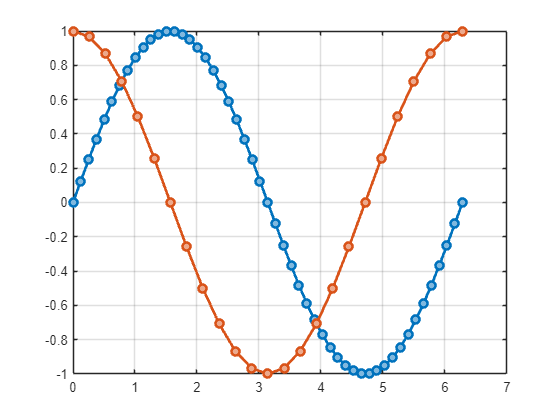

x1 = linspace(0,2*pi,51);
x2 = linspace(0,2*pi,25);
y1 = sin(x1);
y2 = cos(x2);

multiplot(x1,y1,x2,y2)

**Calling with varying inputs**

These calls to `multiplot` currently error, but you will fix in this activity.

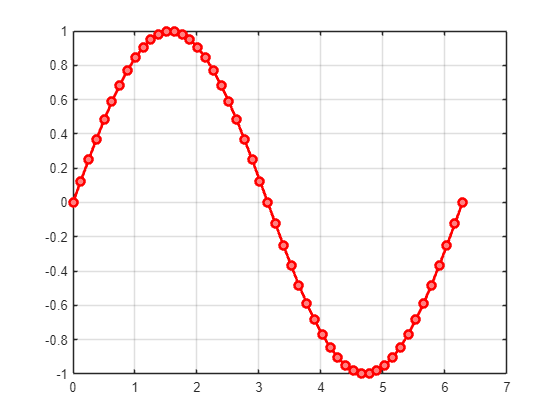

multiplot(x1,y1,"r")

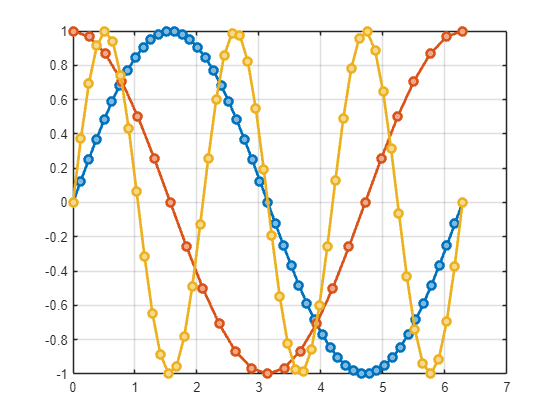


x3 = linspace(0,2*pi,50);
y3 = sin(3*x3);
multiplot(x1,y1,x2,y2,x3,y3)

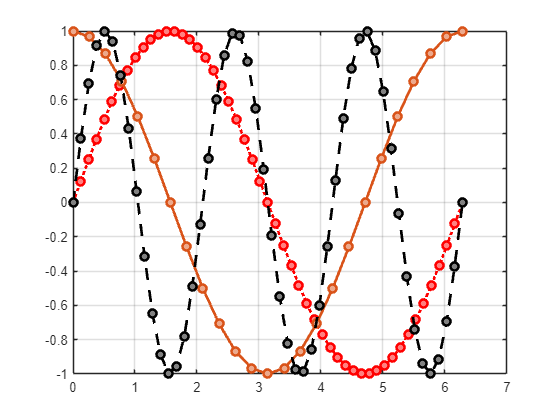


multiplot(x1,y1,"r:",x2,y2,x3,y3,"k*--")

# Plot multiple lines with line specifications

`x1,y1,x2,y2,x3,y3...` are the inputs to plot.

## Examples

`multiplot(x1,y1,x2,y2)`

`multiplot(x,y,``"r"``)`

`multiplot(x1,y1,x2,y2,x3,y3)`

`multiplot(x1,y1,``"r:"``,x2,y2,x3,y3,``"k*--"``)`

The function `multiplot` makes a customized plot for two pairs of (x, y) data. To do this, it uses the built-in `plot` function. However, the `plot` function can accept any number of pairs of data, as well as text inputs that represent style specifications:

 `plot``(``x``,``y``,``"r"``)`

 `plot``(``x1``,``y1``,``x2``,``y2``,``x3``,``y3``)`

 `plot``(``x1``,``y1``,``"r:"``,``x2``,``y2``,``x3``,``y3``,``"k*--"``)`

function multiplot(varargin)
    % Make plots
    figure
    p = plot(varargin{:},'LineWidth',2,'Marker','o');
    grid on
    
    % You do not need to edit this
    for k = 1:numel(p)
        % Changing marker colors to lighter version of the line color
        p(k).MarkerFaceColor = min((p(k).Color+1)/2,1);
    end
end